# Transparent ellipse params

The transparent ellipse has the parameters:

`[x, y, area, eccentricity, theta]`

Consider an ellipse with these transparent parameters:

pTransparent = [0, 0, 100, 0.75, pi/2];

This ellipse has its center (x, y) at the origin [0, 0], and an area (a) of 100 units.

The parameter (e) describes the non-linear eccentricity of the ellipse. This is related to the linear eccentricity of an ellipse (the ratio of the minor and makor axis length) as follows:


$$\frac{\textrm{minor}}{\textrm{major}}=\sqrt{1-e^2 }$$


Thus, `e=0.75` corresponds to a linear eccentricity of 2:3.

The theta value is in units of radians. As an ellipse is symmetric about its major and minor axes, we need define theta only over the range of [0 - pi]. A value of `pi/2` corresponds to an ellipse with a major axis aligned with the vertical axis.

We can convert from transparent form to explicit form with the command:

pExplicit = ellipse_transparent2ex(pTransparent)'

pExplicit =          0         0    6.9371    4.5885    1.5708


corresponding to center (cx,cy), semi-major and semi-minor axes (a and b) and angle of tilt (theta).

We can convert from explicit parameters to implicit parameters:

pImplicit = ellipse_ex2im(pExplicit)

pImplicit =     0.0474   -0.0000    0.0208         0         0   -0.9987


corresponding to the parameters of the equation:


$$Ax^2 +\textrm{Bxy}+Cy^2 +\textrm{Dx}+\textrm{Ey}+F$$


The plots below show how variation in the transparent ellipse parameters relate to the shape of an ellipse.

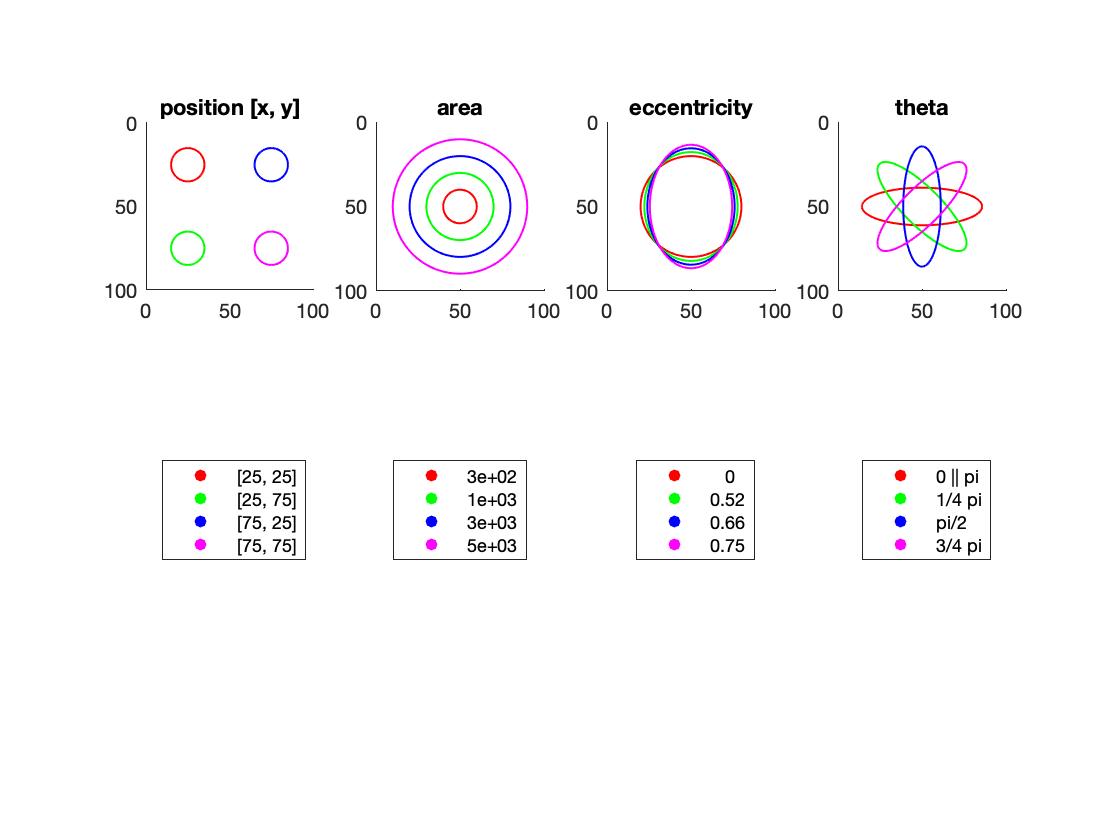

%% Make some plots
figure;
colors={[1 0 0],[0 1 0],[0 0 1],[1 0 1]};

%% Vary the center of a circular ellipse
% Plot the ellipses
subplot(2,4,1);
ylim([0 100]);
xlim([0 100]);
axis square
hold on
firstPlot = true;
index=1;
for x=25:50:75
    for y=25:50:75
        if firstPlot
            set (gca,'Ydir','reverse')
            firstPlot=false;
        end
        transparentEllipseParams = [x, y, pi*10.^2, 0, 0];
        implicitEllipseParams = ellipse_ex2im(ellipse_transparent2ex(transparentEllipseParams));
        fh=@(x,y) implicitEllipseParams(1).*x.^2 +implicitEllipseParams(2).*x.*y +implicitEllipseParams(3).*y.^2 +implicitEllipseParams(4).*x +implicitEllipseParams(5).*y +implicitEllipseParams(6);
        fimplicit(fh,[0, 100, 0, 100],'Color', colors{index},'LineWidth',1);
        index=index+1;
    end
end
title('position [x, y]');

% Add a legend
hSub = subplot(2,4,5);
for ii=1:4
    scatter(nan, nan,1,'filled','MarkerFaceColor',colors{ii});
    hold on
end
set(hSub, 'Visible', 'off');
legend({'[25, 25]','[25, 75]', '[75, 25]','[75, 75]'},'Location','northoutside');


%% vary the area of a circular ellipse
% Plot the ellipses
subplot(2,4,2);
ylim([0 100]);
xlim([0 100]);
axis square
hold on
firstPlot = true;
for ii = 1:4
    vals(ii) = pi*(ii*10).^2;
    if firstPlot
        set (gca,'Ydir','reverse')
        firstPlot=false;
    end
    transparentEllipseParams = [50, 50, vals(ii), 0, 0];
    implicitEllipseParams = ellipse_ex2im(ellipse_transparent2ex(transparentEllipseParams));
    fh=@(x,y) implicitEllipseParams(1).*x.^2 +implicitEllipseParams(2).*x.*y +implicitEllipseParams(3).*y.^2 +implicitEllipseParams(4).*x +implicitEllipseParams(5).*y +implicitEllipseParams(6);
    fimplicit(fh,[0, 100, 0, 100],'Color', colors{ii},'LineWidth',1);
end
title('area');

% Add a legend
hSub = subplot(2,4,6);
for ii=1:4
    scatter(nan, nan,1,'filled','MarkerFaceColor',colors{ii});
    hold on
end
set(hSub, 'Visible', 'off');
legend(num2str(vals',0),'Location','northoutside');


%% vary the eccentricity of an ellipse
% Plot the ellipses
subplot(2,4,3);
ylim([0 100]);
xlim([0 100]);
axis square
hold on
firstPlot = true;
for ii = 1:4
    vals(ii) = axes2ecc(1, 1/(ii/6+(5/6)));
    if firstPlot
        set (gca,'Ydir','reverse')
        firstPlot=false;
    end
    transparentEllipseParams = [50, 50, pi*30.^2, vals(ii), pi/2];
    implicitEllipseParams = ellipse_ex2im(ellipse_transparent2ex(transparentEllipseParams));
    fh=@(x,y) implicitEllipseParams(1).*x.^2 +implicitEllipseParams(2).*x.*y +implicitEllipseParams(3).*y.^2 +implicitEllipseParams(4).*x +implicitEllipseParams(5).*y +implicitEllipseParams(6);
    fimplicit(fh,[0, 100, 0, 100],'Color', colors{ii},'LineWidth',1);
end
title('eccentricity');

% Add a legend
hSub = subplot(2,4,7);
for ii=1:4
    scatter(nan, nan,1,'filled','MarkerFaceColor',colors{ii});
    hold on
end
set(hSub, 'Visible', 'off');
legend(num2str(vals',2),'Location','northoutside');


%% vary the theta of an ellipse
% Plot the ellipses
subplot(2,4,4);
ylim([0 100]);
xlim([0 100]);
axis square
hold on
firstPlot = true;
for ii = 1:4
vals(ii) = ((ii-1)*(pi/4));
    if firstPlot
        set (gca,'Ydir','reverse')
        firstPlot=false;
    end
    transparentEllipseParams = [50, 50, pi*20.^2, 0.95, vals(ii)];
    implicitEllipseParams = ellipse_ex2im(ellipse_transparent2ex(transparentEllipseParams));
    fh=@(x,y) implicitEllipseParams(1).*x.^2 +implicitEllipseParams(2).*x.*y +implicitEllipseParams(3).*y.^2 +implicitEllipseParams(4).*x +implicitEllipseParams(5).*y +implicitEllipseParams(6);
    fimplicit(fh,[0, 100, 0, 100],'Color', colors{ii},'LineWidth',1);
end
title('theta');

% Add a legend
hSub = subplot(2,4,8);
for ii=1:4
    scatter(nan, nan,1,'filled','MarkerFaceColor',colors{ii});
    hold on
end
set(hSub, 'Visible', 'off');
legend({'0 || pi','1/4 pi','pi/2','3/4 pi'},'Location','northoutside');